# Práctica 1

# Introducción al procesamiento de imágenes en MATLAB (I)

Las imágenes en MatLab son tratadas como matrices bidimensionales de números enteros, por lo que se pueden utilizar todas las funciones de procesamiento de matrices que incorpora MatLab. Para imágenes en color se emplean matrices de tres dimensiones, donde la tercera dimensión representa los niveles de rojo, verde y azul de cada uno de los píxeles que componen la imagen.

- Imagen grises => im(fila, columna), nivel de gris del píxel de coordenadas x, y;

- Imagen color => im(fila, columna, banda), nivel de la componente banda del píxel de coordenadas x, y.

CARGAR UNA IMAGEN (FORMATO ESTANDAD, tif, gif, jpg, bmp, …).

- < imagen> = imread (‘<nombre de fichero>’) ;

CONVERTIR IMAGEN A DOUBLE

- < imagen> = double (< imagen>) ;

NOTA: Algunas operaciones requieren que la matriz esté en formato doble, como es el caso de ‘surf’.

## VISUALIZAR IMÁGENES

#### Imagen completa: imshow (<imagen>,[ ]) 

-    => Si los valores son float o double, se asumen entre 0 y 1.

-    => Usa la paleta óptima calculada según la imagen (puede omitirse)

- figure => abre una nueva ventana

- colormap => cambia la paleta utilizada

- axis on => visualiza los ejes de la imagen

- colorbar => muestra la paleta utilizada

- subplot => permite mostrar varias imágenes en una misma figura

#### Líneas y columnas

- plot (<imagen>(<fila>,:));

- plot (<imagen>(:,<columna>));

- => NOTA: el comando plot también se puede emplear para dibujar sobre una imagen se previamente se ha bloqueado la figura ‘hold on’

#### Visualizar imágenes como superficies

- surf (double(<imagen>))

- shading interp => interpola los colores para una mejor visualización.

### EJERCICIOS

1. Cargue las imágenes ‘Connector 01.jpg’ y ‘Cables14.jpg’ y muéstrelas en dos figuras. (im1 e im2).

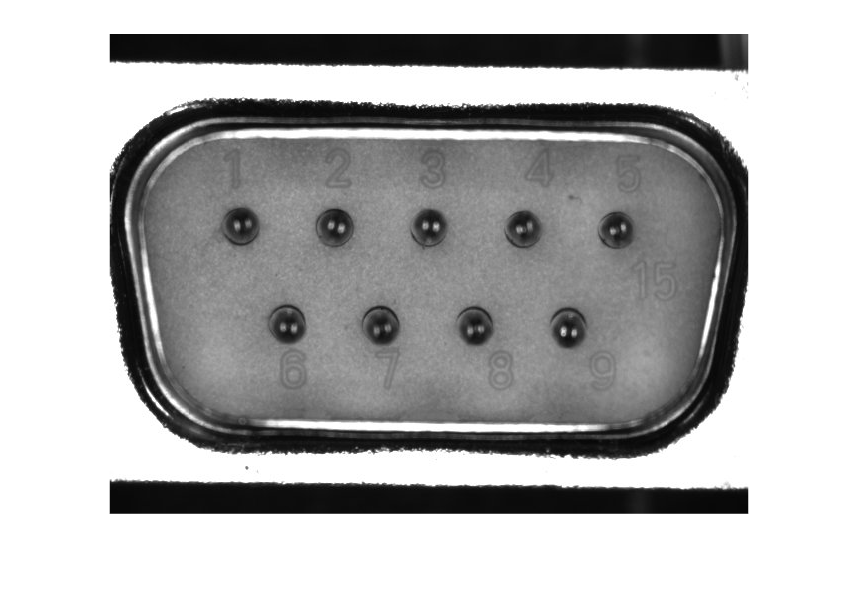

im1 = imread("Connector 01.jpg");
imshow(im1);

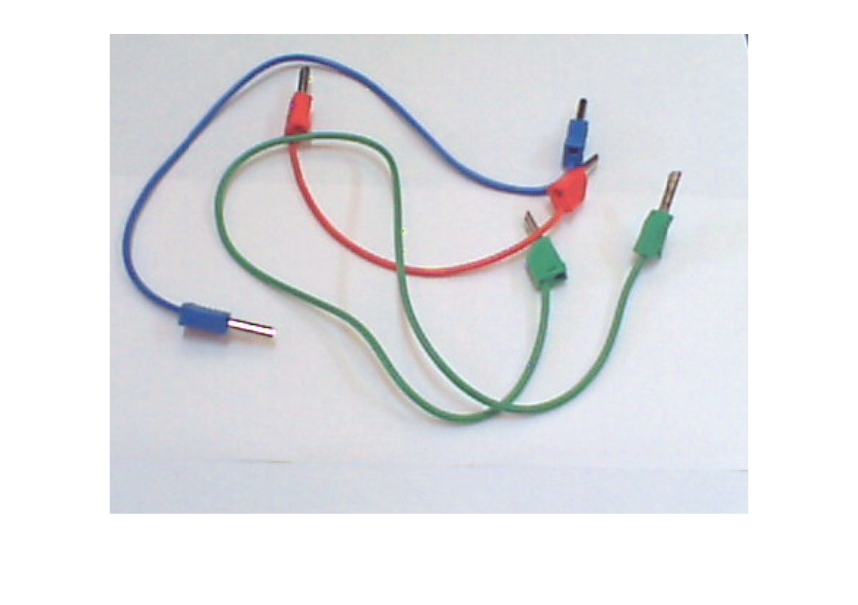

im2 = imread("cables14.jpg");
imshow(im2);

2. Visualice las dos imágenes (im1 e im2) en una misma figura.

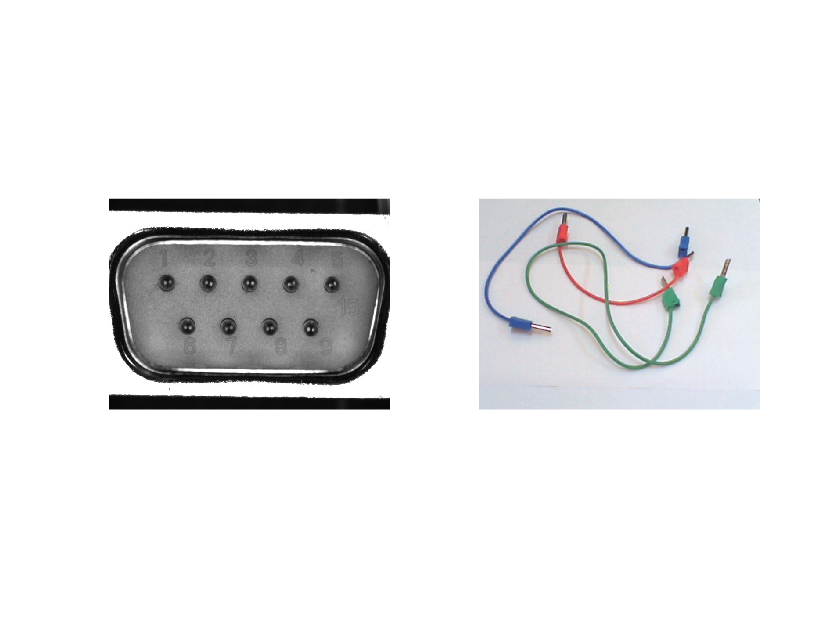

figure
subplot(121);
imshow(im1);
subplot(1,2,2)
imshow(im2);

3. Visualice en una nueva figura la imagen im1 como una superficie (colormap gray, shading interp). Cambie el punto de vista de la imagen mediante el ratón y observe el nivel como alturas.

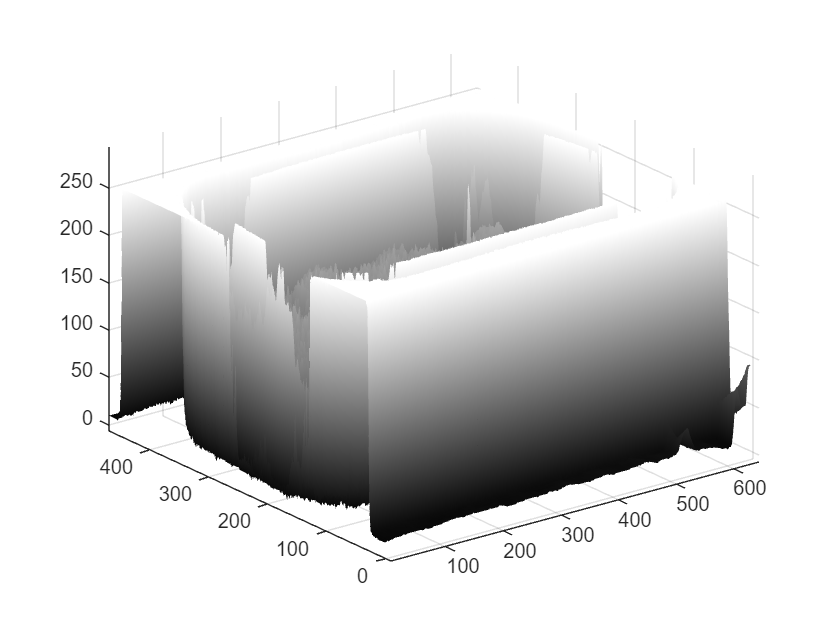

figure
surf(double(im1));
shading interp;
colormap gray;

4. Muestre en una nueva figura la línea 185 de la imagen im1 (comando plot) y la imagen im1 sobre la que debe resaltar dicha fila en verde (plot sobre la imagen). Pruebe con otras líneas.

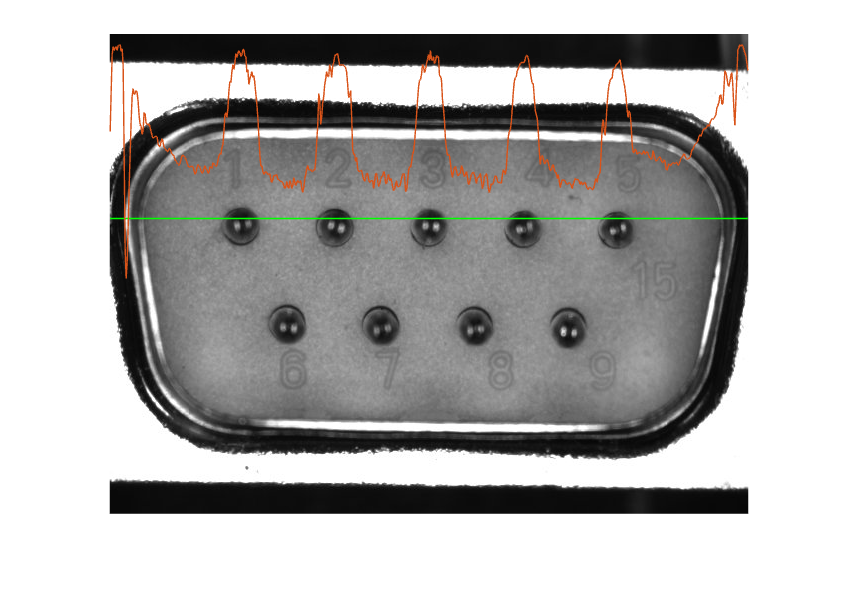

imshow(im1);
hold on
[ymax, xmax] = size(im1);
plot([0, xmax], [185, 185], "g");
lin185 = im1(185, :);
plot(lin185');

## REDUCIR ESCALA Y TOMAR SUBIMÁGENES

EJEMPLOS:

- im1 = im (1:2:end,1:2:end); => cambio de resolución a ½

- im2 = im (1:end/2,1:end/2); => tomar subimagen (primer cuadrante)

### EJERCICIO:

5. Muestre en una figura la imagen im1 con resolución completa, con resolución ½, con resolución ¼ y con resolución 1/8 (subplot (2,2,n ))

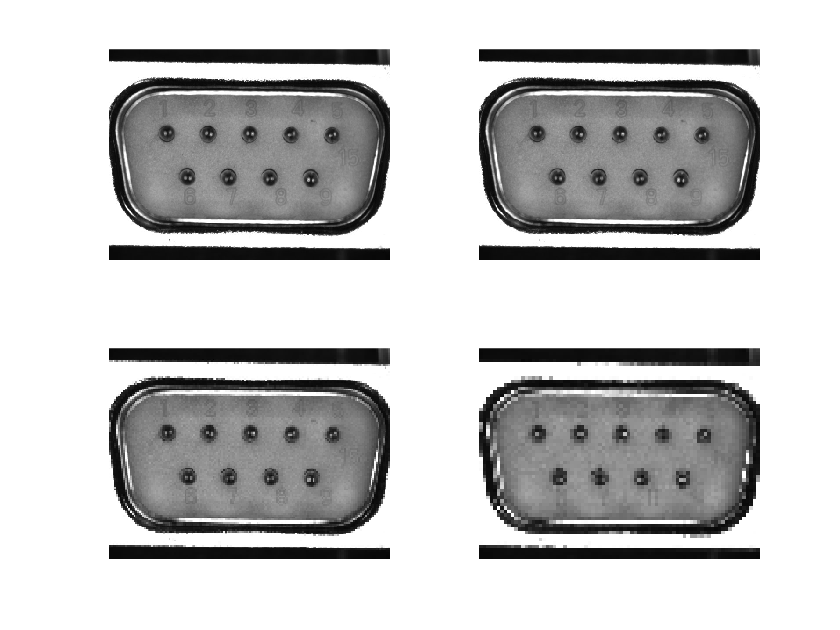

figure
subplot(2,2,1);
imshow(im1);
subplot(2,2,2);
imshow(im1(1:2:end, 1:2:end));
subplot(2, 2, 3);
imshow(im1(1:4:end, 1:4:end));
subplot(2, 2, 4);
imshow(im1(1:8:end, 1:8:end));

## CONVERSION DE IMÁGENES

- <imagenHSV> = rgb2hsv (<imagenRGB>);

- <imagenGRISES> = <imagenHSV>(:,:,3); => extrae la componente correspondiente al brillo.

### EJERCICIOS:

6. Muestre en una figura la imagen en color im2 y sus tres componentes R, G y B. (subplot)

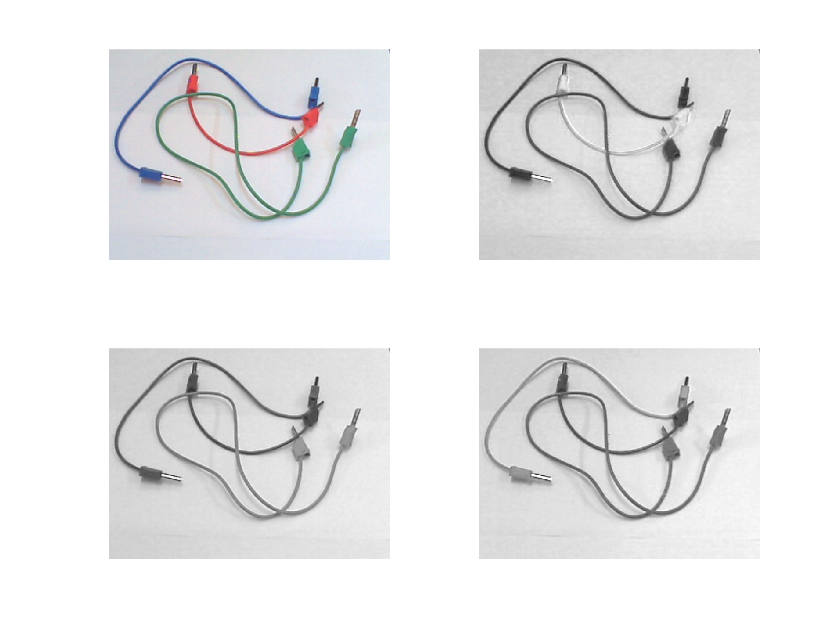

figure
subplot(2,2,1);
imshow(im2);
subplot(2,2,2);
imshow(im2(:,:,1));
subplot(2, 2, 3);
imshow(im2(:,:,2));
subplot(2, 2, 4);
imshow(im2(:,:,3));

7. Transforme la imagen im2 de formato RGB a formato HSV (im3) y muestre en una figura la imagen im2 y sus componentes H, S y V. (subplot)

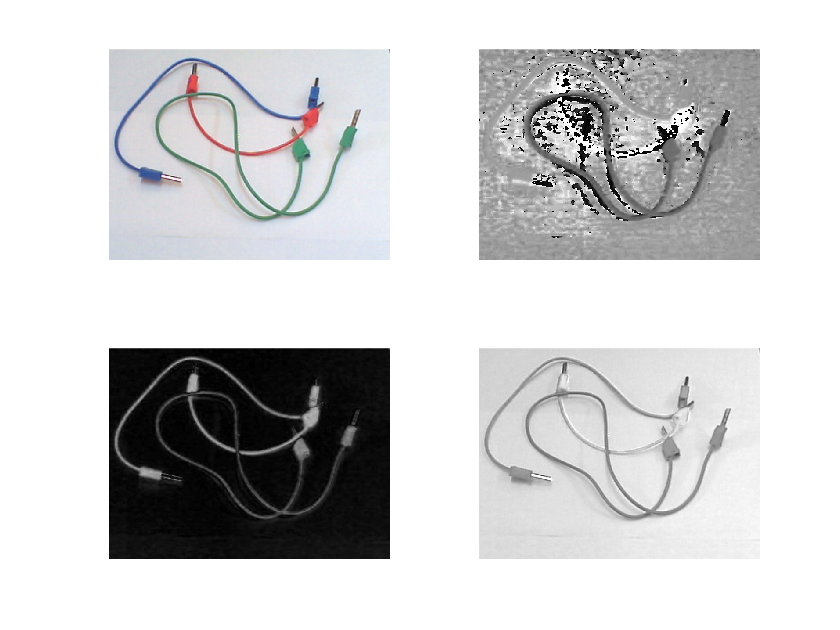

figure
subplot(2,2,1);
imshow(im2);
subplot(2,2,2);
im2hsv = rgb2hsv(im2);
imshow(im2hsv(:,:,1));
subplot(2, 2, 3);
imshow(im2hsv(:,:,2));
subplot(2, 2, 4);
imshow(im2hsv(:,:,3));

8. Muestre en una nueva figura el resultado de multiplicar las componentes de SATURACIÓN y MATIZ de la imagen im3 ¿qué se consigue con esto?

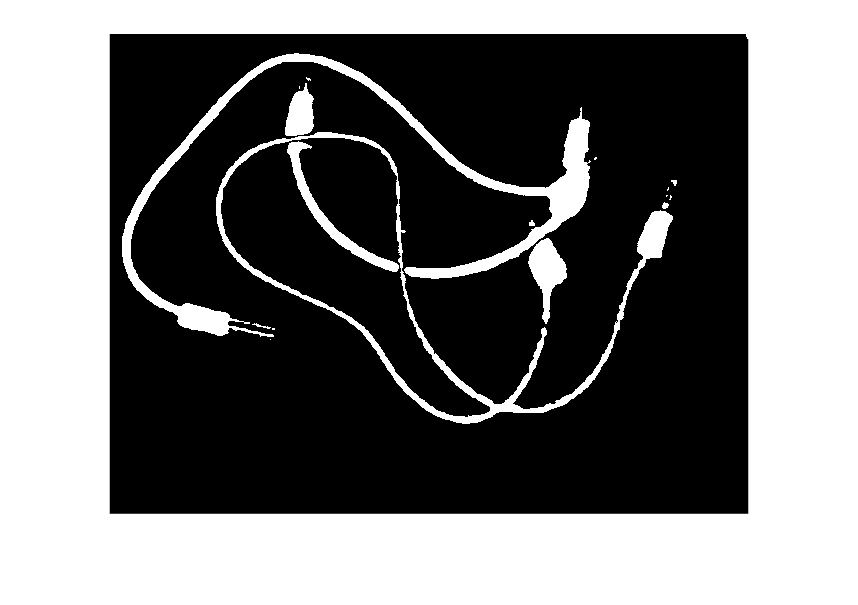

%im2mul = im2hsv(:,:,1)>0.2;
im2mul = im2hsv(:,:,2)>0.2;
%im2mul = im2hsv(:,:,1).*im2hsv(:,:,2);
%im2mul = im2hsv(:,:,1).*im2hsv(:,:,2)>0.5;
%im2mul = im2hsv(:,:,1).*(im2hsv(:,:,2)>0.5);
%im2mul = im2hsv(:,:,1).*(im2hsv(:,:,2)>0.2);
figure
imshow(im2mul)

9. Amplifique el resultado obtenido en el ejercicio anterior multiplicándolo por 2.

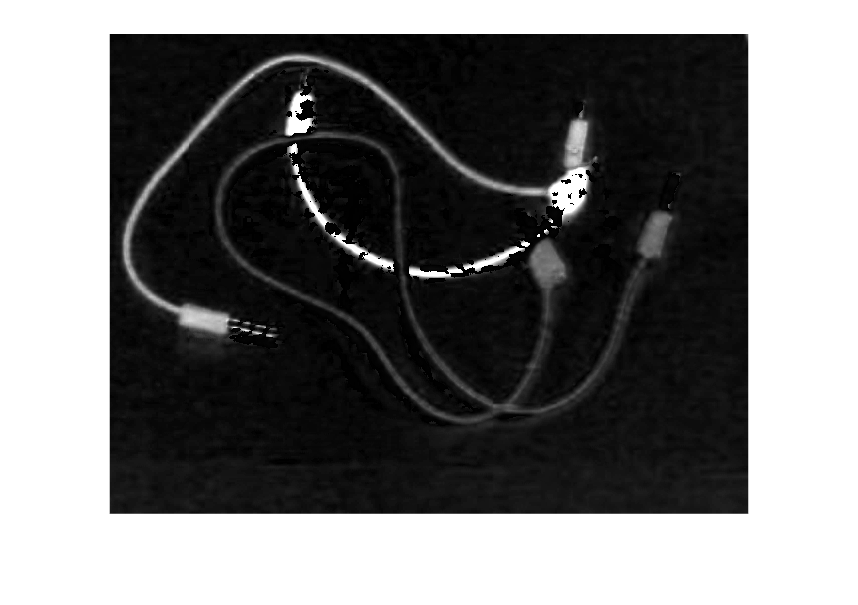

figure
imshow(2*im2mul);

## CAPTURAR COORDENADAS

- ginput => captura las coordenadas de un conjunto de puntos utilizando el ratón.

- [<x>, <y>] = ginput (<n>);

### EJERCICIOS:

10. Analice y compruebe el funcionamiento del siguiente SCRIPT, el cual permite marcar 9 puntos sobre la imagen im1 y almacenar para cada punto sus coordenadas en la imagen (fila y columna) y su nivel de gris. Cada vez que se selecciona un punto este se marca sobre la imagen mediante un ‘*’ y se etiqueta con un número (1, 2, 3, 4 …) (comando text)

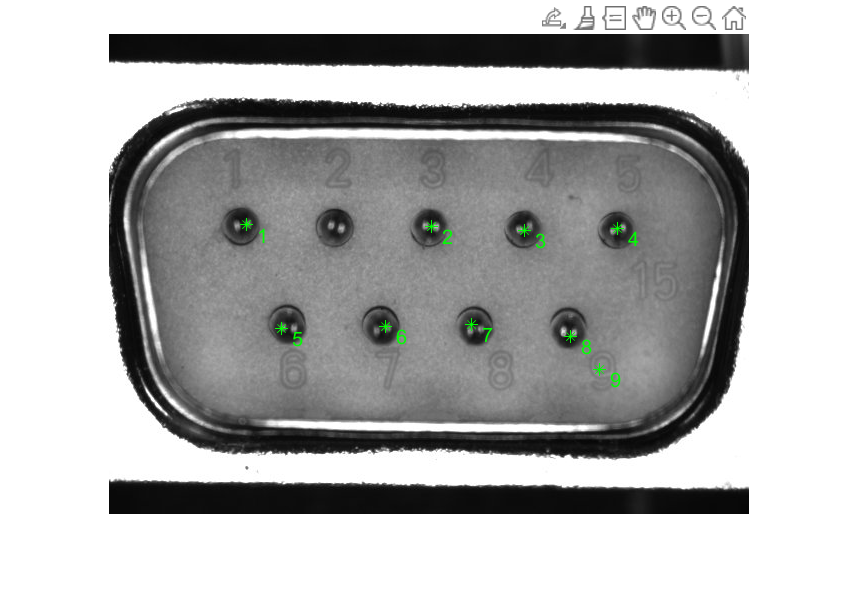

imshow (im1); hold on
for ind = 1:9
    [x,y] = ginput(1);
    x = round(x);
    y = round(y);
    puntos (ind, :) = ([y x double(im1(y,x))]);
    plot (x, y, 'g*');
    text (x+10,y+10,num2str(ind),'Color','g');
end

puntos % Muestra el resultado.

puntos =    191   138   109
   193   323    38
   197   416    68
   195   509    59
   295   173   135
   293   277   102
   291   363    39
   303   462    26
   336   491   134


11. Realice un SCRIPT que permita selección una sub-imagen a partir de dos puntos marcados con el ratón y empleelo para seleccionar uno de los pines en la imagen im1.

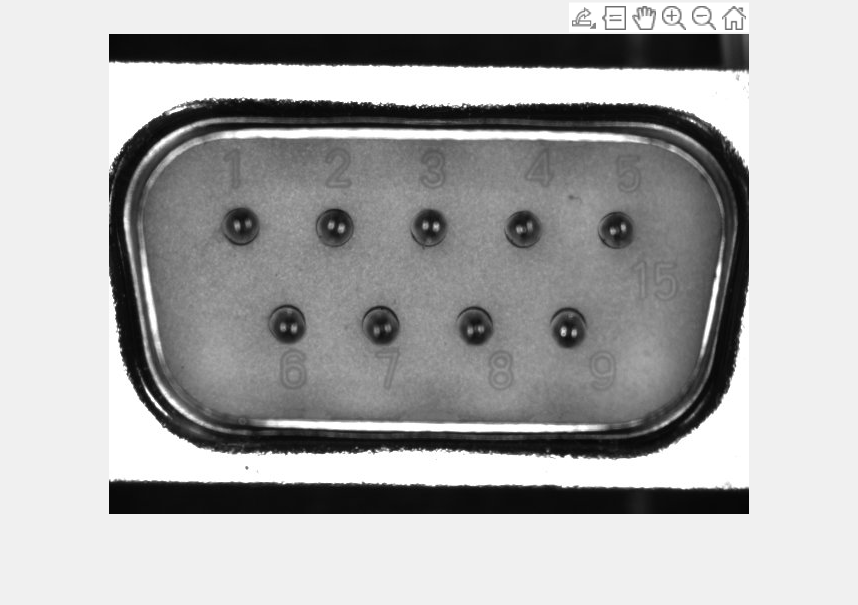

figure
imshow(im1)
[x1,y1] =ginput(1);
[x2,y2] =ginput(1);

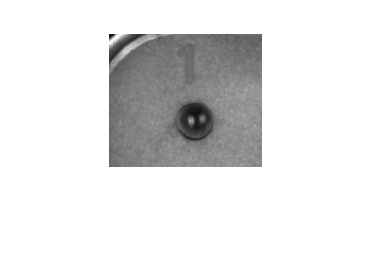

figure
imcrop = im1(round(y1):round(y2), round(x1):round(x2), :);
imshow(imcrop);